7a

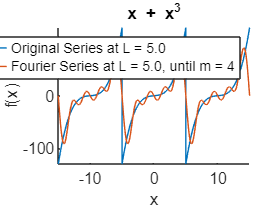

clc, clear, clf

syms x
f = @sum_fourier;
fu = @(x) x + x^3;


hold on
title("x + x^3")

interval = 5; % ini L

fus = @(x) piecewise(x < -interval, fu(x + 2*interval), ...
    (-interval < x) & (x < interval), fu(x), ...
    x > interval, fu(x - 2* interval));


fplot([fus(x), f(x, interval)])

ylim([fu(-interval) fu(interval)])
xlim([-3*interval 3*interval])

oriLegend = sprintf("Original Series at L = %.1f", interval);
fourierLegend = sprintf("Fourier Series at L = %.1f, until m = 4", interval);

legend([oriLegend, fourierLegend])

xlabel("x")
ylabel("f(x)")

7b

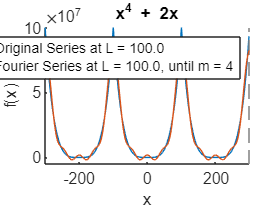

clc, clear, clf

syms x
f = @sum_fourier_b;
fu = @(x) x^4 + 2 * x;

figure

hold on
title("x^4 + 2x")

interval = 100; % ini L

fus = @(x) piecewise(x < -interval, fu(x + 2*interval), ...
    (-interval < x) & (x < interval), fu(x), ...
    x > interval, fu(x - 2* interval));

fplot([fus(x), f(x, interval)])

bot = -(interval^4 / 5) / 4;

ylim([bot fu(interval)])
xlim([-3*interval 3*interval])

oriLegend = sprintf("Original Series at L = %.1f", interval);
fourierLegend = sprintf("Fourier Series at L = %.1f, until m = 4", interval);

legend([oriLegend, fourierLegend])

xlabel("x")
ylabel("f(x)")

7c

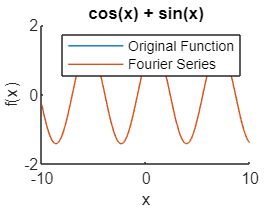

clc, clear, clf

syms x
f = @(x) sin(x) + cos(x);

figure

hold on
title("cos(x) + sin(x)")

interval = pi;

fplot([cos(x) + sin(x), f(x)])

ylim([-2 2])
xlim([-10 10])

legend2 = sprintf("Fourier Series", interval);

legend(["Original Function", legend2])

xlabel("x")
ylabel("f(x)")

function f = f(x, L)
    f = 0;

    for m = 1:4
        f = f + (6 * (L / (m * pi))^3 - (L + L^3) / (m * pi)) * cos(m * pi) * sin(m * pi * x / L);
    end

    f = f * 2;
end

function f = sum_fourier_b(x, L)
    f = 0;

    for m = 1:4
        f = f + cos(m * pi) * ((8 * L^4 / (m * pi)^2) * (1 - 6 / (m * pi)^2) * cos(m * pi * x/L) + (-4 * L / (m * pi)) * sin(m * pi * x/L));
    end

    f = f + L^4 / 5;
end